clear
clf
%1st problem (b)

a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
L = 1; %Length of the domain (m)
x = linspace(0,1,1000);

T = 0;
t = 0; %time (s) - need to vary
for i = 1:100000
    B = (4*L)./((i.*pi)^2);
    D = sin(i*pi/2);
    e = exp((-a*t).*(((i.*pi)./L)^2));
    s = sin((i.*pi.*x)./L);
    T = T + (D.*B.*e.*s);
end

T_1 = 0;
t_1 = 10; %time (s) - need to vary
for j = 1:100000
    B_1 = (4*L)./((j.*pi)^2);
    D_1 = sin(j*pi/2);
    e_1 = exp((-a*t_1).*(((j.*pi)./L)^2));
    s_1 = sin((j.*pi.*x)./L);
    T_1 = T_1 + (D_1.*B_1.*e_1.*s_1);
end

T_2 = 0;
t_2 = 50; %time (s) - need to vary
for k = 1:100000
    B_2 = (4*L)./((k.*pi)^2);
    D_2 = sin(k*pi/2);
    e_2 = exp((-a*t_2).*(((k.*pi)./L)^2));
    s_2 = sin((k.*pi.*x)./L);
    T_2 = T_2 + (D_2.*B_2.*e_2.*s_2);
end

T_3 = 0;
t_3 = 100; %time (s) - need to vary
for l = 1:100000
    B_3 = (4*L)./((l.*pi)^2);
    D_3 = sin(l*pi/2);
    e_3 = exp((-a*t_3).*(((l.*pi)./L)^2));
    s_3 = sin((l.*pi.*x)./L);
    T_3 = T_3 + (D_3.*B_3.*e_3.*s_3);
end

T_4 = 0;
t_4 = 1000; %time (s) - need to vary
for m = 1:100000
    B_4 = (4*L)./((m.*pi)^2);
    D_4 = sin(m*pi/2);
    e_4 = exp((-a*t_4).*(((m.*pi)./L)^2));
    s_4 = sin((m.*pi.*x)./L);
    T_4 = T_4 + (D_4.*B_4.*e_4.*s_4);
end

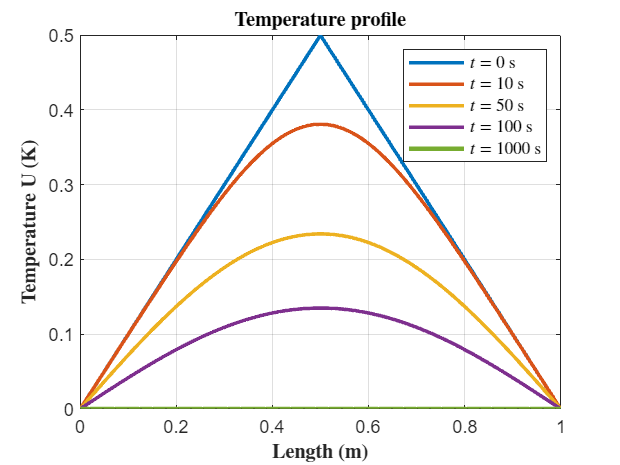

%Plots
h1 = plot(x, T,'LineWidth', 2);
grid on
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m)}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
hold on
h2 = plot(x, T_1,'LineWidth', 2);
h3 = plot(x, T_2,'LineWidth', 2);
h4 = plot(x, T_3,'LineWidth', 2);
h5 = plot(x, T_4,'LineWidth', 2.5);
legend([h1, h2, h3, h4, h5], '$t = 0$ s', '$t = 10$ s', '$t = 50$ s', '$t = 100$ s', '$t = 1000$ s', 'Interpreter', 'latex');

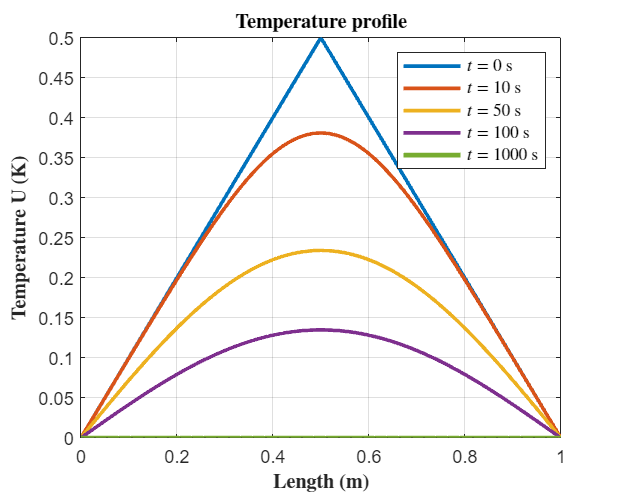

%Saving plot
outputFileName = 'Problem_1_b.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');